clear all; close all; clc;
% Leer el archivo CSV
datos = readtable('datos\caudales_biobio.csv');

% Crear vector de fechas
fechas = datetime(datos.agno, datos.mes, datos.dia);

% Extraer valores de caudal
caudal = datos.valor;

% Definir rango completo de fechas
anio_inicio = min(datos.agno);
anio_fin = max(datos.agno);
fechas_completas = datetime(anio_inicio, 1, 1):datetime(anio_fin, 12, 31);

% Crear vector de caudales completo (inicializado con NaN)
caudal_completo = NaN(length(fechas_completas), 1);

% Llenar con los datos existentes
fechas_datos = datetime(datos.agno, datos.mes, datos.dia);
for i = 1:length(fechas_datos)
    idx = find(fechas_completas == fechas_datos(i), 1);
    if ~isempty(idx)
        caudal_completo(idx) = datos.valor(i);
    end
end

fprintf('Datos cargados: %d registros\n', length(caudal));

Datos cargados: 15259 registros


fprintf('Datos caudal completo: %d registros\n', length(caudal_completo));

Datos caudal completo: 18628 registros


fprintf('Período: %s a %s\n\n', datestr(fechas(1)), datestr(fechas(end)))

Período: 24-Sep-1970 a 05-Jun-2020



2. CÁLCULO DEL PROMEDIO ANUAL


% Obtener años únicos
anios_unicos = unique(anio_inicio:anio_fin);

% Inicializar vectores
promedio_anual = zeros(length(anios_unicos), 1);
anios_completos = anios_unicos;

% Calcular promedio para cada año
for i = 1:length(anios_unicos)
    idx = datos.agno == anios_unicos(i);
    promedio_anual(i) = mean(caudal_completo(idx), 'omitnan');
end

% Mostrar estadísticas
fprintf('Promedio general: %.2f m³/s\n', mean(promedio_anual, 'omitnan'));

Promedio general: 1017.48 m³/s


fprintf('Desviación estándar: %.2f m³/s\n', std(promedio_anual, 'omitnan'));

Desviación estándar: 273.66 m³/s


fprintf('Máximo anual: %.2f m³/s (año %d)\n', max(promedio_anual), anios_completos(promedio_anual == max(promedio_anual)));

Máximo anual: 1898.53 m³/s (año 1973)


fprintf('Mínimo anual: %.2f m³/s (año %d)\n\n', min(promedio_anual), anios_completos(promedio_anual == min(promedio_anual)));

Mínimo anual: 532.57 m³/s (año 2005)



3. CLIMATOLOGÍA ANUAL (Promedio mensual para cada mes del año)

% Inicializar matriz para climatología
climatologia = zeros(12, 1);
meses_nombre = {'Ene', 'Feb', 'Mar', 'Abr', 'May', 'Jun', 'Jul', 'Ago', 'Sep', 'Oct', 'Nov', 'Dic'};

% Calcular promedio para cada mes (todos los años)
for mes = 1:12
    idx = datos.mes == mes;
    climatologia(mes) = mean(caudal(idx), 'omitnan');
    fprintf('%s: %.2f\n', meses_nombre{mes}, climatologia(mes));
end

Ene: 357.43
Feb: 257.57
Mar: 261.17
Abr: 381.46
May: 908.62
Jun: 1616.78
Jul: 1783.53
Ago: 1587.82
Sep: 1386.02
Oct: 1187.67
Nov: 949.51
Dic: 622.26


4. PROMEDIOS DE INVIERNO Y VERANO

Definir meses de invierno (JAS) y verano (EFM)

Invierno: Julio (7), Agosto (8), Septiembre (9)

Verano: Enero (1), Febrero (2), Marzo (3)

Inicializar vectores estacionales

promedio_invierno = zeros(length(anios_unicos), 1); 
promedio_verano = zeros(length(anios_unicos), 1); 
anios_analisis = anios_unicos;

% Calcular promedios estacionales por año
for i = 1:numel(anios_unicos)
    anio = anios_unicos(i);

    mask_anio = datos.agno == anio;
    mask_inv  = ismember(datos.mes, [7 8 9]);   % JAS
    mask_ver  = ismember(datos.mes, [1 2 3]);   % EFM

    promedio_invierno(i) = mean(caudal(mask_anio & mask_inv), 'omitnan');
    fprintf('Promedio de caudal\n Año: %d \n Promedio: %.2f\n', anios_unicos(i) ,promedio_invierno(i));
    promedio_verano(i)   = mean(caudal(mask_anio & mask_ver), 'omitnan');
end

Promedio de caudal
 Año: 1970 
 Promedio: 855.29
Promedio de caudal
 Año: 1971 
 Promedio: 1781.75
Promedio de caudal
 Año: 1972 
 Promedio: 2084.74
Promedio de caudal
 Año: 1973 
 Promedio: 2112.62
Promedio de caudal
 Año: 1974 
 Promedio: 1190.30
Promedio de caudal
 Año: 1975 
 Promedio: 1346.03
Promedio de caudal
 Año: 1976 
 Promedio: 901.34
Promedio de caudal
 Año: 1977 
 Promedio: NaN
Promedio de caudal
 Año: 1978 
 Promedio: NaN
Promedio de caudal
 Año: 1979 
 Promedio: NaN
Promedio de caudal
 Año: 1980 
 Promedio: NaN
Promedio de caudal
 Año: 1981 
 Promedio: NaN
Promedio de caudal
 Año: 1982 
 Promedio: 2469.04
Promedio de caudal
 Año: 1983 
 Promedio: 1474.49
Promedio de caudal
 Año: 1984 
 Promedio: 2044.32
Promedio de caudal
 Año: 1985 
 Promedio: 1447.60
Promedio de caudal
 Año: 1986 
 Promedio: 1410.66
Promedio de caudal
 Año: 1987 
 Promedio: 2075.49
Promedio de caudal
 Año: 1988 
 Promedio: 1504.66
Promedio de caudal
 Año: 1989 
 Promedio: 1478.42
Promedio de caudal
 Añ


% Mostrar estadísticas estacionales
fprintf('INVIERNO (Julio-Agosto-Septiembre):\n');

INVIERNO (Julio-Agosto-Septiembre):


fprintf('  Promedio: %.2f m³/s\n', mean(promedio_invierno, 'omitnan'));

  Promedio: 1570.60 m³/s


fprintf('  Desviación estándar: %.2f m³/s\n', std(promedio_invierno, 'omitnan'));

  Desviación estándar: 533.55 m³/s


fprintf('  Máximo: %.2f m³/s\n', max(promedio_invierno));

  Máximo: 2754.07 m³/s


fprintf('  Mínimo: %.2f m³/s\n\n', min(promedio_invierno));

  Mínimo: 670.85 m³/s




fprintf('VERANO (Enero-Febrero-Marzo):\n');

VERANO (Enero-Febrero-Marzo):


fprintf('  Promedio: %.2f m³/s\n', mean(promedio_verano, 'omitnan'));

  Promedio: 300.94 m³/s


fprintf('  Desviación estándar: %.2f m³/s\n', std(promedio_verano, 'omitnan'));

  Desviación estándar: 128.55 m³/s


fprintf('  Máximo: %.2f m³/s\n', max(promedio_verano));

  Máximo: 736.76 m³/s


fprintf('  Mínimo: %.2f m³/s\n\n', min(promedio_verano));

  Mínimo: 99.12 m³/s



Prueba

disp(table(anios_unicos(:), promedio_invierno(:), promedio_verano(:), ...
          'VariableNames', {'Anio', 'PromedioInvierno', 'PromedioVerano'}));

    Anio    PromedioInvierno    PromedioVerano
    ____    ________________    ______________

    1970         855.29                NaN    
    1971         1781.8             342.94    
    1972         2084.7             311.15    
    1973         2112.6             282.06    
    1974         1190.3             287.67    
    1975           1346             264.98    
    1976         901.34             280.22    
    1977            NaN             725.81    
    1978            NaN                NaN    
    1979            NaN                NaN    
    1980            NaN                NaN    
    1981            NaN                NaN    
    1982           2469             242.17    
    1983         1474.5             368.73    
    1984         2044.3             247.85    
    1985         1447.6             441.76    
    1986         1410.7             264.27    
    

5. GRÁFICOS DE SERIES DE TIEMPO

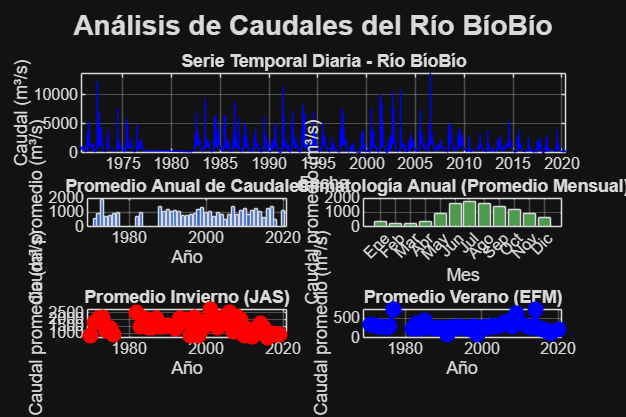

% Figura 1: Serie temporal completa
figure('Position', [100 100 1200 800]);

% Subplot 1: Serie diaria completa
subplot(3,2,1:2)
plot(fechas, caudal, 'b-', 'LineWidth', 0.5);
grid on;
xlabel('Fecha');
ylabel('Caudal (m³/s)');
title('Serie Temporal Diaria - Río BíoBío');
xlim([min(fechas) max(fechas)]);

% Subplot 2: Promedio anual
subplot(3,2,3)
bar(anios_completos, promedio_anual, 'FaceColor', [0.2 0.4 0.8]);
grid on;
xlabel('Año');
ylabel('Caudal promedio (m³/s)');
title('Promedio Anual de Caudales');
xlim([min(anios_completos)-1 max(anios_completos)+1]);

% Subplot 3: Climatología mensual
subplot(3,2,4)
bar(1:12, climatologia, 'FaceColor', [0.3 0.6 0.3]);
grid on;
xlabel('Mes');
ylabel('Caudal promedio (m³/s)');
title('Climatología Anual (Promedio Mensual)');
set(gca, 'XTick', 1:12, 'XTickLabel', meses_nombre);
xtickangle(45);

% Subplot 4: Series estacionales (Invierno)
subplot(3,2,5)
plot(anios_analisis, promedio_invierno, 'ro-', 'LineWidth', 2, 'MarkerFaceColor', 'r');
grid on;
xlabel('Año');
ylabel('Caudal promedio (m³/s)');
title('Promedio Invierno (JAS)');
xlim([min(anios_analisis)-1 max(anios_analisis)+1]);

% Subplot 5: Series estacionales (Verano)
subplot(3,2,6)
plot(anios_analisis, promedio_verano, 'bo-', 'LineWidth', 2, 'MarkerFaceColor', 'b');
grid on;
xlabel('Año');
ylabel('Caudal promedio (m³/s)');
title('Promedio Verano (EFM)');
xlim([min(anios_analisis)-1 max(anios_analisis)+1]);

% Ajustar espaciado
sgtitle('Análisis de Caudales del Río BíoBío', 'FontSize', 14, 'FontWeight', 'bold');

6. FIGURA COMPARATIVA INVIERNO VS VERANO

figure('Position', [150 150 1200 600]);

subplot(2,1,1)
plot(anios_analisis, promedio_invierno, 'r-o', 'LineWidth', 2, 'MarkerSize', 6, 'DisplayName', 'Invierno (JAS)');
hold on;
plot(anios_analisis, promedio_verano, 'b-s', 'LineWidth', 2, 'MarkerSize', 6, 'DisplayName', 'Verano (EFM)');
grid on;
xlabel('Año');
ylabel('Caudal promedio (m³/s)');
title('Comparación Estacional: Invierno vs Verano');
legend('Location', 'best');
xlim([min(anios_analisis)-1 max(anios_analisis)+1]);

7. ESTIMACIÓN DE TENDENCIAS

fprintf('=== ANÁLISIS DE TENDENCIAS ===\n');

=== ANÁLISIS DE TENDENCIAS ===



% Eliminar NaN para el análisis de tendencias
idx_valido_inv = ~isnan(promedio_invierno);
idx_valido_ver = ~isnan(promedio_verano);

anios_inv = anios_analisis(idx_valido_inv);
caudal_inv = promedio_invierno(idx_valido_inv);

anios_ver = anios_analisis(idx_valido_ver);
caudal_ver = promedio_verano(idx_valido_ver);

% Ajuste lineal para INVIERNO
p_invierno = polyfit(anios_inv, caudal_inv, 1);
tendencia_inv = polyval(p_invierno, anios_inv);
r2_inv = 1 - sum((caudal_inv - tendencia_inv).^2) / sum((caudal_inv - mean(caudal_inv)).^2);

% Ajuste lineal para VERANO
p_verano = polyfit(anios_ver, caudal_ver, 1);
tendencia_ver = polyval(p_verano, anios_ver);
r2_ver = 1 - sum((caudal_ver - tendencia_ver).^2) / sum((caudal_ver - mean(caudal_ver)).^2);

% Mostrar resultados de tendencias
fprintf('TENDENCIA INVIERNO:\n');

TENDENCIA INVIERNO:


fprintf('  Pendiente: %.4f m³/s por año\n', p_invierno(1));

  Pendiente: -6.7331 m³/s por año


fprintf('  Intercepto: %.2f m³/s\n', p_invierno(2));

  Intercepto: 15011.45 m³/s


fprintf('  Cambio total en el período: %.2f m³/s\n\n', p_invierno(1) * (max(anios_inv) - min(anios_inv)));

  Cambio total en el período: -329.92 m³/s




fprintf('TENDENCIA VERANO:\n');

TENDENCIA VERANO:


fprintf('  Pendiente: %.4f m³/s por año\n', p_verano(1));

  Pendiente: -0.3966 m³/s por año


fprintf('  Intercepto: %.2f m³/s\n', p_verano(2));

  Intercepto: 1092.56 m³/s


fprintf('  Cambio total en el período: %.2f m³/s\n\n', p_verano(1) * (max(anios_ver) - min(anios_ver)));

  Cambio total en el período: -19.43 m³/s



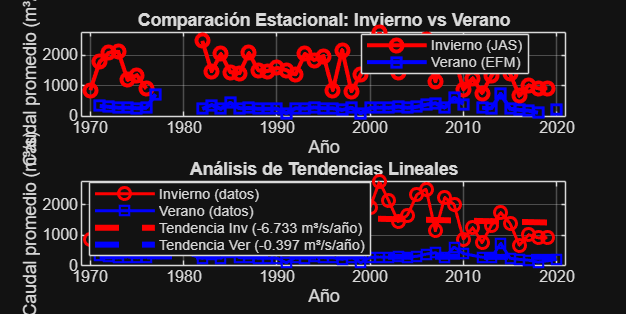


% Graficar con tendencias
subplot(2,1,2)
plot(anios_inv, caudal_inv, 'ro-', 'LineWidth', 1.5, 'MarkerSize', 6, 'DisplayName', 'Invierno (datos)');
hold on;
plot(anios_ver, caudal_ver, 'bs-', 'LineWidth', 1.5, 'MarkerSize', 6, 'DisplayName', 'Verano (datos)');
plot(anios_inv, tendencia_inv, 'r--', 'LineWidth', 3, 'DisplayName', sprintf('Tendencia Inv (%.3f m³/s/año)', p_invierno(1)));
plot(anios_ver, tendencia_ver, 'b--', 'LineWidth', 3, 'DisplayName', sprintf('Tendencia Ver (%.3f m³/s/año)', p_verano(1)));
grid on;
xlabel('Año');
ylabel('Caudal promedio (m³/s)');
title('Análisis de Tendencias Lineales');
legend('Location', 'best');
xlim([min(anios_analisis)-1 max(anios_analisis)+1]);